# Configuração do FM para análise de Banda

clear all;
close all;
clc;


## Configura modulador

n=1;

switch n
    case 1
        Kf = 10;
        wc = 30*pi;
        wm = 2*pi;
        Ap = pi;
    case 2
        Kf = 10;
        wc = 50*pi;
        wm = pi;
        Ap = pi;
    case 3
        Kf = 15;
        wc = 50*pi;
        wm = 2*pi;
        Ap = 1*pi;
    otherwise
        Kf = 5;
        wc = 40*pi;
        wm = pi;
        Ap = 2*pi;
end




## Simula o modulador

options = simset('solver','ode45','MaxStep',0.001,'InitialStep',0.001,'ReturnWorkspaceOutputs', 'on');
y = sim('ModemFM',2,options);

## Análise temporal

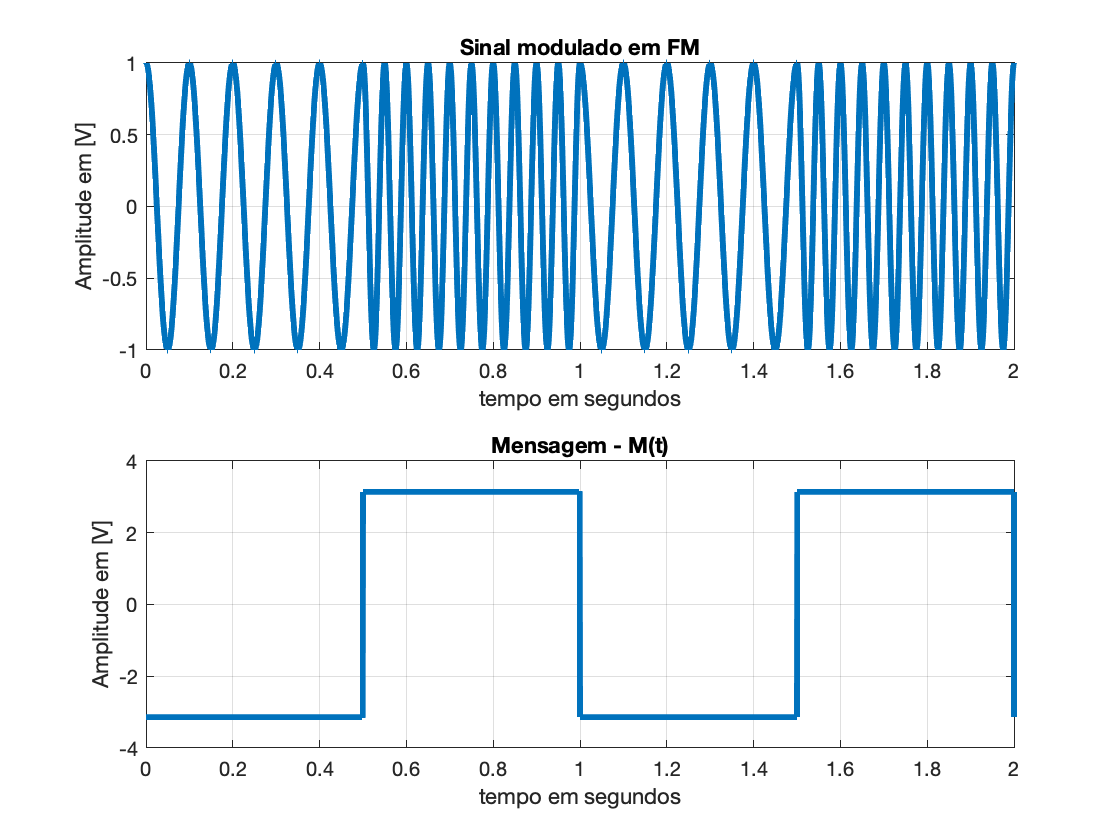

M = y.Mensagem;
FM = y.FM;
tempo =  y.tout;

figure(1)

subplot(2,1,1)

plot(tempo,FM,'LineWidth',3);
title('Sinal modulado em FM');
ylabel('Amplitude em [V]');
xlabel('tempo em segundos');
grid;

subplot(2,1,2)

plot(tempo,M,'LineWidth',3);
title('Mensagem - M(t)');
ylabel('Amplitude em [V]');
xlabel('tempo em segundos');
grid;

## Análise espectral

%%% acertando o eixo frequência

if rem(length(tempo),2)==0.
    
    NP = length(tempo)-1;     % número de pontos
    Ts = tempo(end)/NP;     % tempo de amostragem
    fs = 1/Ts;              % frequência de amostragem
    
    f  = linspace(-fs/2,fs/2,NP)    % eixo frequência
    
    M = M(1:end-1);
    FM = FM(1:end-1);
    Mw = fft(M/(max(M)));
    FMw = fft(FM);

else
    
    NP = length(tempo);     % número de pontos
    Ts = tempo(end)/NP;     % tempo de amostragem
    fs = 1/Ts;              % frequência de amostragem
    
    f  = linspace(-fs/2,fs/2,NP)    % eixo frequência
    
    Mw = fft(M/(max(M)));
    FMw = fft(FM);
    
end

f =  -500.2500 -499.7498 -499.2495 -498.7493 -498.2490 -497.7487 -497.2485 -496.7482 -496.2480 -495.7477 -495.2475 -494.7473 -494.2470 -493.7468 -493.2465 -492.7462 -492.2460 -491.7457 -491.2455 -490.7452 -490.2450 -489.7448 -489.2445 -488.7442 -488.2440 -487.7437 -487.2435 -486.7432 -486.2430 -485.7428 -485.2425 -484.7423 -484.2420 -483.7417 -483.2415 -482.7412 -482.2410 -481.7407 -481.2405 -480.7403 -480.2400 -479.7397 -479.2395 -478.7392 -478.2390 -477.7387 -477.2385 -476.7382 -476.2380 -475.7378


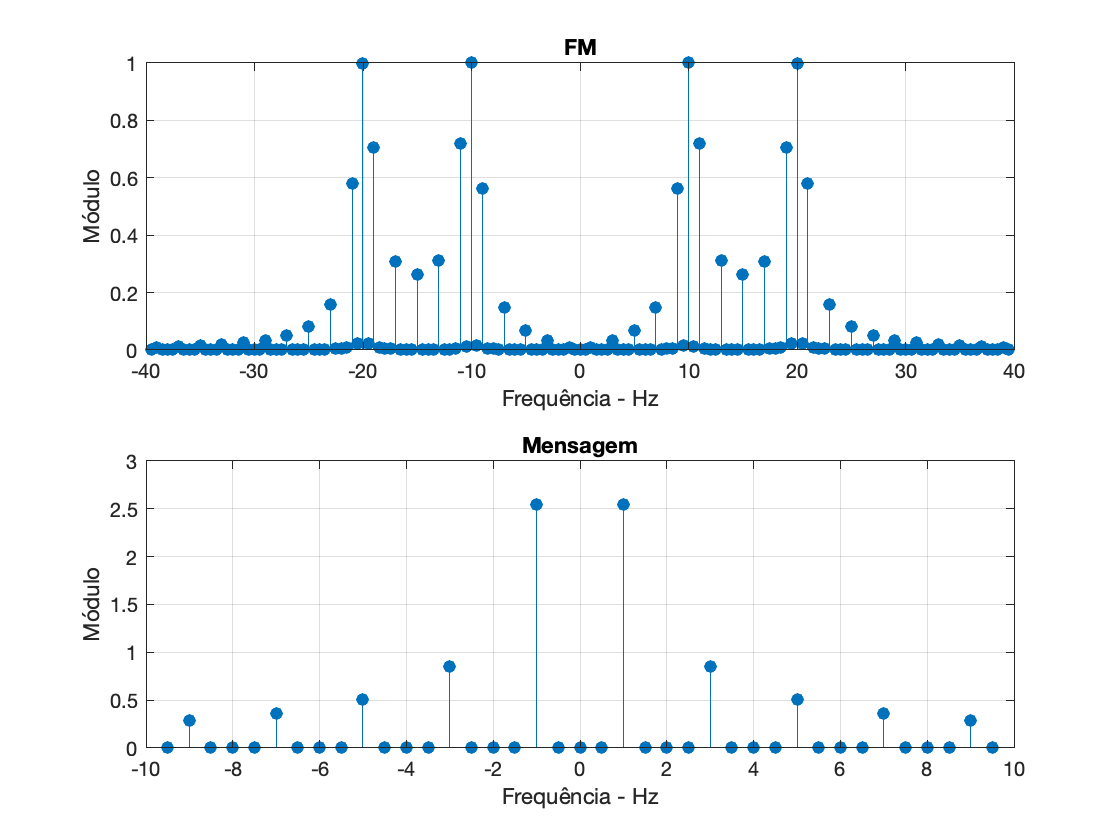




subplot(2,1,1)
stem(f,fftshift(abs(FMw))/max(abs(FMw)),'filled')
title('FM')
xlabel('Frequência - Hz')
ylabel('Módulo')
 xlim([-40 40])
% ylim([0 5100])
grid


subplot(2,1,2)
stem(f,fftshift(abs(Mw))/max(abs(FMw)),'filled')
title('Mensagem')
xlabel('Frequência - Hz')
ylabel('Módulo')
xlim([-10 10])
% ylim([0 15000])
grid